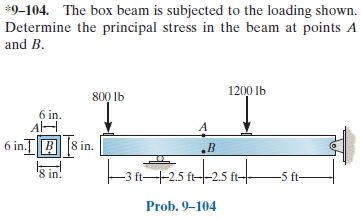

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-104RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-104RP-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

[M V] = deal(default_struct('a', 'b'));
Y = deal(M);
[sigma_bending tau_shear] = deal(M);
[sigmax sigmay tauxy] = deal(M);
[sigmaxp sigmayp tauxyp thetap] = deal(M);
[sigmaxs sigmays tauxys thetas] = deal(M);

# beam

b = beam;
b = b.add('concentrated', 'force', -800*u.lbf, 0);
b = b.add('reaction', 'force', 'R1', 3*u.ft);
b = b.add('concentrated', 'force', -1200*u.lbf, 8*u.ft);
b = b.add('reaction', 'force', 'R2', 13*u.ft);
b.L = 13*u.ft;

# section properties

Bo = 8*u.in;
Bi = 6*u.in;
b.I = rewrite((Bo^4-Bi^4)/12, u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{20736\,\left(x-3\,\mathrm{ft}\right)\,\left(4\,x^{2}+12\,x\,\mathrm{ft}-87\,{\mathrm{ft}}^{2}\right)}{7\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\leq 3\,\mathrm{ft}\\ \frac{62208\,\left(x-3\,\mathrm{ft}\right)\,\left(7\,x^{2}-102\,x\,\mathrm{ft}+268\,{\mathrm{ft}}^{2}\right)}{35\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(3\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -\frac{62208\,\left(x-13\,\mathrm{ft}\right)\,\left(3\,x^{2}-78\,x\,\mathrm{ft}+332\,{\mathrm{ft}}^{2}\right)}{35\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{62208\,\left(41\,{\mathrm{ft}}^{2}-4\,x^{2}\right)}{7\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\leq 3\,\mathrm{ft}\\ \frac{62208\,\left(21\,x^{2}-246\,x\,\mathrm{ft}+574\,{\mathrm{ft}}^{2}\right)}{35\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(3\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -\frac{62208\,\left(9\,x^{2}-234\,x\,\mathrm{ft}+1346\,{\mathrm{ft}}^{2}\right)}{35\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -800\,x\,\mathrm{lbf} & \text{ if }x\leq 3\,\mathrm{ft}\\ 120\,\left(7\,x-41\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }x\in \left(3\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -360\,\left(x-13\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -800\,\mathrm{lbf} & \text{ if }x\leq 3\,\mathrm{ft}\\ 840\,\mathrm{lbf} & \text{ if }x\in \left(3\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -360\,\mathrm{lbf} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} R_{1} & 1640\,\mathrm{lbf}\\ R_{2} & 360\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

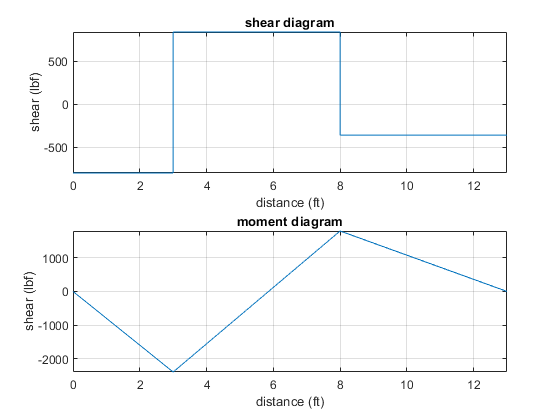

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});

# loads at points A

M.a = m(5.5*u.ft);
M_a = M.a %#ok<NASGU> 

$$M\_a = -300\,\mathrm{ft}\,\mathrm{lbf}$$

V.a = v(5.5*u.ft);
V_a = V.a %#ok<NASGU> 

$$V\_a = 840\,\mathrm{lbf}$$

# loads at points B

[M.b V.b] = deal(M.a, V.a);
M_b = M.b %#ok<NASGU> 

$$M\_b = -300\,\mathrm{ft}\,\mathrm{lbf}$$

V_b = V.b %#ok<NASGU> 

$$V\_b = 840\,\mathrm{lbf}$$

# stresses at point A

% ----------------
% - bending stress
% ----------------
Y.a = 4*u.in;
b.I = rewrite(b.I, u.in);
sigma_bending.a = rewrite(-M.a*Y.a/b.I, u.psi);
sigma_bending_a = vpa(sigma_bending.a, 4) %#ok<NASGU> 

$$sigma\_bending\_a = 61.71\,\mathrm{psi}$$

# stresses at point B

% ----------------
% - bending stress
% ----------------
Y.b = -3*u.in;
sigma_bending.b = rewrite(-M.b*Y.b/b.I, u.psi);
sigma_bending_b = vpa(sigma_bending.b, 4) %#ok<NASGU> 

$$sigma\_bending\_b = -46.29\,\mathrm{psi}$$

# mohr stresses at point A

sigmax.a = sigma_bending.a;
sigmax_a = vpa(sigmax.a, 4) %#ok<NASGU> 

$$sigmax\_a = 61.71\,\mathrm{psi}$$

sigmay.a = sym(0);
sigmay_a = sigmay.a %#ok<NASGU> 

$$sigmay\_a = 0$$

tauxy.a = sym(0);
tauxy_a = tauxy.a %#ok<NASGU> 

$$tauxy\_a = 0$$

[sigmaxp.a sigmayp.a tauxyp.a thetap.a] = beam.principal(sigmax.a, sigmay.a, tauxy.a);
[sigmaxs.a sigmays.a tauxys.a thetas.a] = beam.max_shear(sigmax.a, sigmay.a, tauxy.a);

# mohr stresses at point B

sigmax.b = sigma_bending.b;
sigmax_b = vpa(sigmax.b, 4) %#ok<NASGU> 

$$sigmax\_b = -46.29\,\mathrm{psi}$$

sigmay.b = sym(0);
sigmay_b = sigmay.b %#ok<NASGU> 

$$sigmay\_b = 0$$

tauxy.b = sym(0);
tauxy_b = tauxy.b %#ok<NASGU> 

$$tauxy\_b = 0$$

[sigmaxp.b sigmayp.b tauxyp.b thetap.b] = beam.principal(sigmax.b, sigmay.b, tauxy.b);
[sigmaxs.b sigmays.b tauxys.b thetas.b] = beam.max_shear(sigmax.b, sigmay.b, tauxy.b);

# mohr's circle for point A

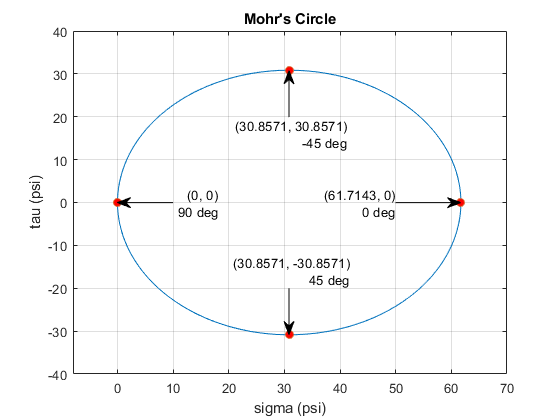

beam.mohr_plot(sigmax.a, sigmay.a, tauxy.a, {'psi'});
axis([-8 70 -40 40]);
xvals = double(separateUnits([sigmaxp.a sigmaxs.a]));
yvals = double(separateUnits([tauxyp.a tauxys.a]));
thetavals = double(separateUnits([thetap.a thetas.a]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = 50;
      y1 = 0;
    case 2
      x1 = 10;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = 20;
    case 4
      x1 = xvals(4);
      y1 = -20;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# mohr's circle for point B

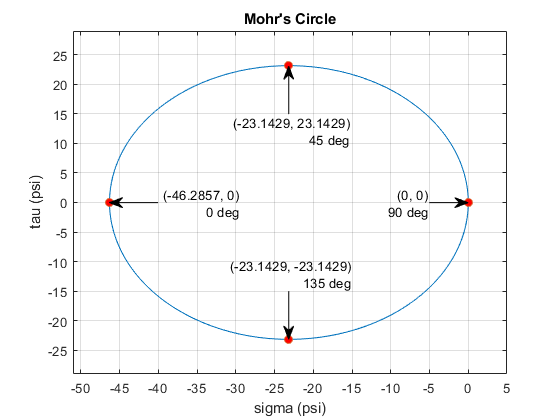

beam.mohr_plot(sigmax.b, sigmay.b, tauxy.b, {'psi'});
axis([-51 5 -29 29]);
xvals = double(separateUnits([sigmaxp.b sigmaxs.b]));
yvals = double(separateUnits([tauxyp.b tauxys.b]));
thetavals = double(separateUnits([thetap.b thetas.b]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = -40;
      y1 = 0;
    case 2
      x1 = -5;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = 15;
    case 4
      x1 = xvals(4);
      y1 = -15;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear M_a V_a;
clear M_b V_b;
clear sigma_bending_a tau_shear_a;
clear sigma_bending_b tau_shear_b;
clear sigmax_a sigmay_a tauxy_a;
clear sigmax_b sigmay_b tauxy_b;
clear xvals yvals thetavals k x1 y1 x2 y2 text_str;